# **test different methods doing PSD estimate in matlab**

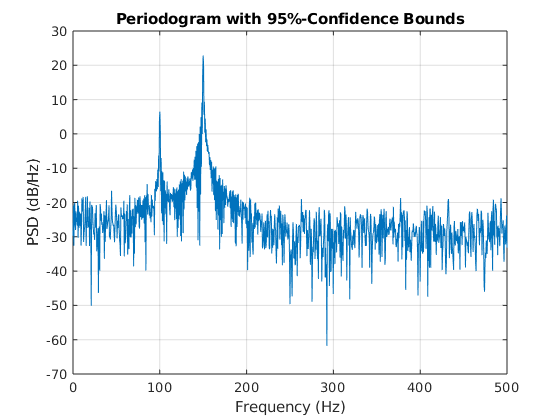


% close all
% clear


%% warm-up, use periodogram
fs = 1000;  % sampling rate
t = 0:1/fs:1-1/fs;  % time, 1s
x = 3*cos(2*pi*100*t) + 20*sin(2*pi*150*t) + randn(size(t)); % composed signal
N = length(x);
nfft = pow2(nextpow2(N));   % or N
nfft = 2048;

% Obtain the periodogram PSD estimate with 95%-confidence bounds. Plot the periodogram along with
% the confidence interval and zoom in on the frequency region of interest near 100 and 150 Hz.
[pxx,f,pxxc] = periodogram(x,rectwin(N),nfft,fs,...
    'ConfidenceLevel',0.95);

figure
plot(f,10*log10(pxx))
hold on
% plot(f,10*log10(pxxc),'-.')
grid on

% xlim([85 175])
xlabel('Frequency (Hz)')
ylabel('PSD (dB/Hz)')
title('Periodogram with 95%-Confidence Bounds')

# **Obtain the periodogram using fft.**

Create a signal consisting of a 100Hz sine wave in N(0,1) additive noise. The sampling frequency is 1 kHz. The signal length is  1000 samples. Use the default settings of the random number generator  for reproducible results

%%
rng default
Fs = 1000;  % sampling rate
t = 0:1/Fs:1-1/Fs;  % time is 1s
% x = 3*cos(2*pi*100*t) + 20*cos(2*pi*150*t) + randn(size(t));   


The signal is real-valued and has even length. Because the signal is real-valued, you only need power estimates for the positive or negative frequencies. In  order to conserve the total power, multiply all frequencies that occur  in both sets -- the positive and negative frequencies -- by a factor of 2. Zero frequency (DC) and the Nyquist frequency do not occur twice. Plot  the result.

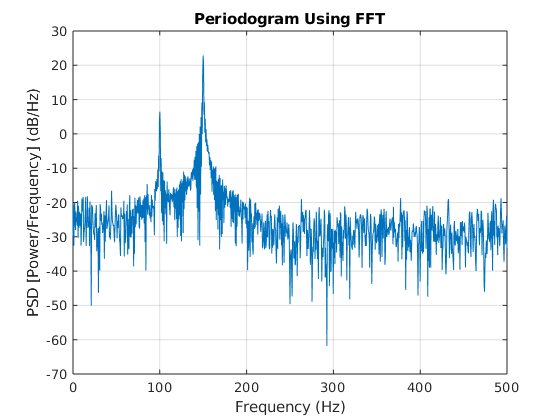

N = length(x);
nfft = pow2(nextpow2(N));   % or N
% nfft = N;
nfft = 2048;
xdft = fft(x,nfft);  % the nfft here is taken as default as the signal length, N
xdft = xdft(1:nfft/2+1);    % half
psdx = abs(xdft).^2/ (Fs*N);    % in the equation, the denominator is always Fs*N no matter what nfft is used
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:Fs/nfft:Fs/2;

figure
plot(freq,10*log10(psdx))
grid on
title('Periodogram Using FFT')
xlabel('Frequency (Hz)')
ylabel('PSD [Power/Frequency] (dB/Hz)')

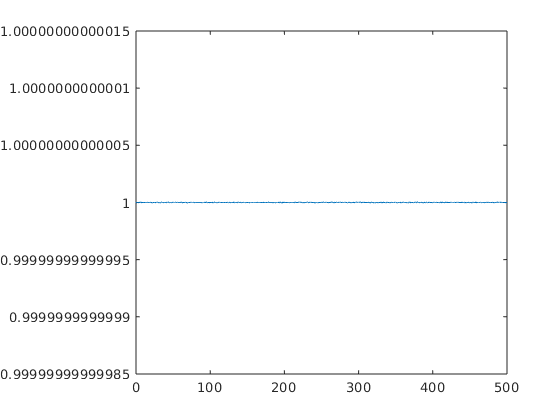

% here, try to use different nfft other than N to test in the equation above
% psdx = abs(xdft).^2/ (Fs*N); plot the division of the two results, to see 
% what is acturally used in the spectrogram, whether to use nfft or N, the
% truth is: N is correct, rather than nfft. THIS in very important to remember
figure
plot(freq,pxx'./psdx)

# **Obtain the PSD with periodgram**

Compute and plot the periodgram with periodgram. Show that the two results are identical. **DO NOT use pxx = periodogram(x) unless you know what it is doing!!!!**

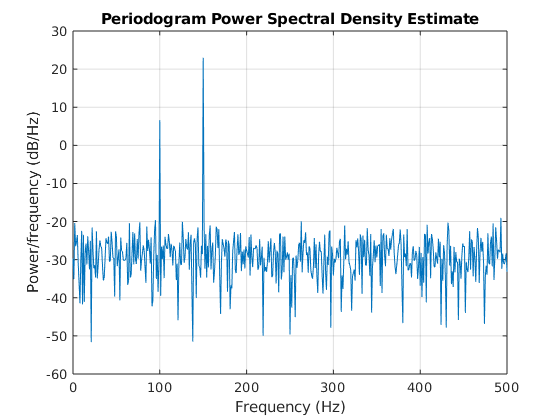

%% x--signal, rectwin(length(x))--window type, length(x)--nfft, Fs--sampling rate
%% window always has the same length as the signal
% periodogram(x,rectwin(length(x)),pow2(nextpow2(N)),Fs,'onesided');
periodogram(x,rectwin(length(x)),N,Fs,'onesided');

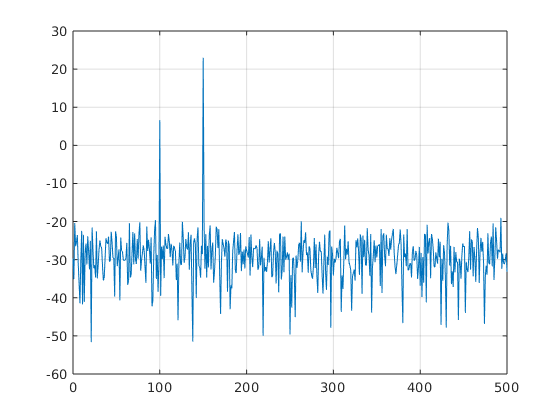

%%% The following is to show the default option of the auto-plot
%%% pxx and ft has the size of nfft/2+1
figure
[pxx,ft]=periodogram(x,rectwin(length(x)),length(x),Fs);
plot(ft,10*log10(pxx));
grid on

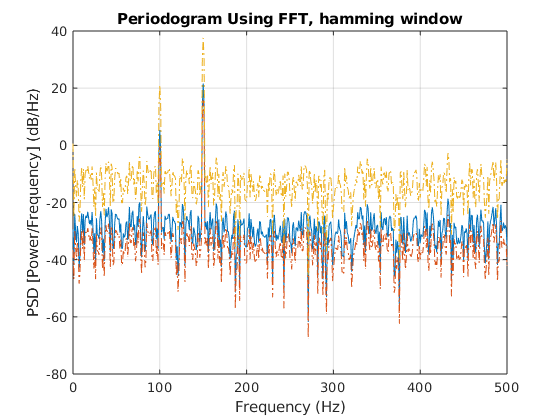

%%% change the window type to hamming instead of rectwin, also with confidence level
figure
[pxx,ft,psdxxc]=periodogram(x,hamming(length(x)),length(x),Fs,'ConfidenceLevel',0.95);
plot(ft,10*log10(pxx)); hold on
grid on
plot(ft,10*log10(psdxxc),'-.')
title('Periodogram Using FFT, hamming window')
xlabel('Frequency (Hz)')
ylabel('PSD [Power/Frequency] (dB/Hz)')

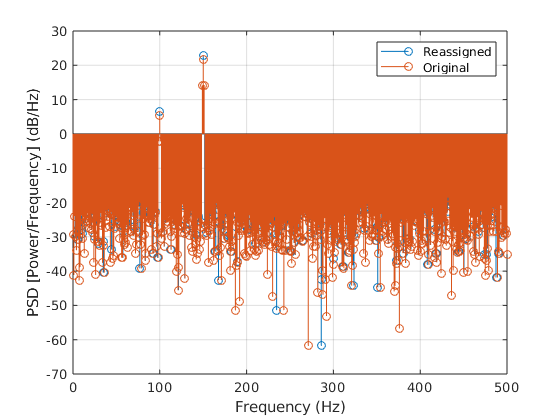

%%% try to use the reassigned option
%%% notice that pun == pxx, fr==ft, the 
figure
[pun,fr] = periodogram(x,hamming(length(x)),length(x),Fs);
[pre,ft,pxx,fx]=periodogram(x,hamming(length(x)),length(x),Fs,'reassigned');
stem(fx,10*log10(pre)); hold on
grid on
stem(ft,10*log10(pxx));
legend('Reassigned','Original');
xlabel('Frequency (Hz)')
ylabel('PSD [Power/Frequency] (dB/Hz)')

# Obtain PSD from pwelch

pwelch pxx=pwelch(x) returns the power spectral density (PSD) estimate,pxx, of the input signal,x, found using Welch's overlapped segment averaging estimator. By default, x is divided into the longest possible segments to obtain as close to but not exceed 8 segments with 50% overlap. Each segment is windowed with a Hamming window. The modified periodograms are averaged to obtain the PSD estimate. If you cannot divide the length of x exactly into an integer number of segments with 50% overlap, x is truncated accordingly.

Say we are using [pxx,f]= pwelch(x,window,noverlap,nfft,fs), 

- where x is input vector 

- **window, window vector of length nfft**

- noverlap, number of overlapped samples for DFT averging

- nfft, number of points in DFT

- fs, sampling rate in Hz

Le length(x)=N.If DFT averaging is not desired, you set nfft equal to N and pwelch takes a single DFT of the windowed vector x. If DFT averaging is desired, you set nfft to a fraction of N and pwelch uses windowed segments of x of length nfft as inputs to the DFT. The  |X(k)|^2 of the multiple DFT's are then averaged.

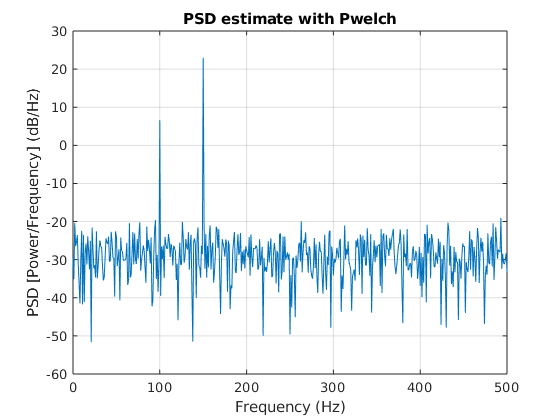

%% Use no averging, so window has the same length as signal, and noverlap=0
figure
[pxx,ft]=pwelch(x,rectwin(length(x)),0,length(x),Fs);
plot(ft,10*log10(pxx));
grid on
title('PSD estimate with Pwelch')
xlabel('Frequency (Hz)')
ylabel('PSD [Power/Frequency] (dB/Hz)')

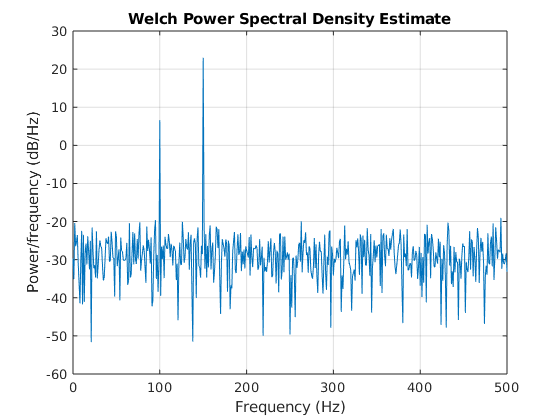


%%% try use auto plotting, is the same!
pwelch(x,rectwin(length(x)),0,length(x),Fs);

Take pwelch as an example, [pxx,f] = pwelch(x, window,0,nfft,fs), pxx is assumed to have the unit of W/Hz, watt. Using Pdb_hz = 10*log10(pxx), we can convert W/Hz to dB/Hz. We can also use the following to convert dB/Hz to dB/bin. First, convert W/Hz to W/bin:

Pbin (W/bin) = pxx (W/Hz) * fs/nfft    Hz/bin

Then, we have in dB: 

PdB_bin = 10*log10(pxx*fs/nfft)     dB/bin

Or PdB_bin = PdB_Hz + 10*log10(fs/nfft)    dB/bin

If we set the noise amplitude to zero, we get PdB_Hz = -5.9176 dB/Hz and PdB_bin= -5.9176 dBW/Hz + 10log10(4000/1024) = 0 dBW = 1 watt 

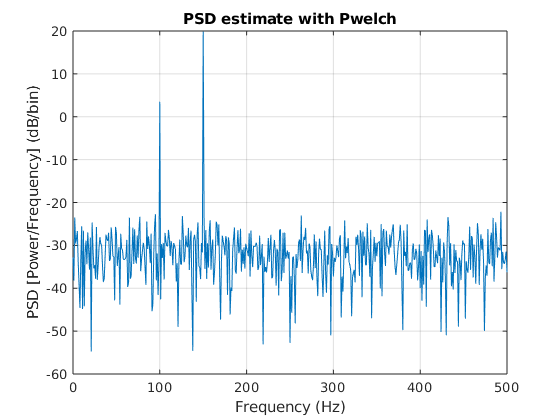

%%% convert dB/Hz to dB/bin
PdB_bin= 10*log10(pxx*fs/nfft);
figure
plot(ft,PdB_bin);
grid on
title('PSD estimate with Pwelch')
xlabel('Frequency (Hz)')
ylabel('PSD [Power/Frequency] (dB/bin)')

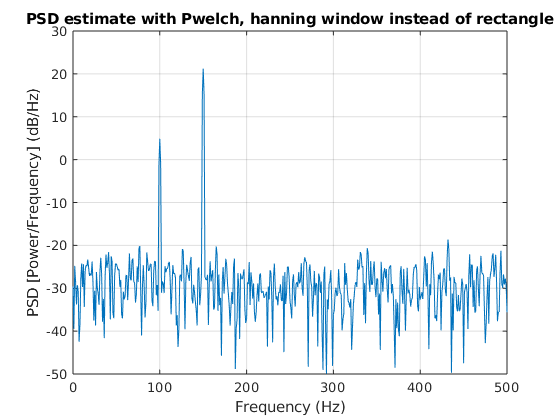


%%% try another windowing method
figure
[pxx,ft]=pwelch(x,hanning(length(x)),0,length(x),Fs);
plot(ft,10*log10(pxx));
grid on
title('PSD estimate with Pwelch, hanning window instead of rectangle')
xlabel('Frequency (Hz)')
ylabel('PSD [Power/Frequency] (dB/Hz)')

### Using averging window

Pwelch takes the DFT of $N_{avg}$ overlapping windows of x, each DFT has the same length of nfft, and then averages the $|X(k)^2|$ of the DFT's. In general, if there are an integer number if segment that cover all samples of N, we have


$$(N_{avg}-1)*D+nfft=N$$


where D = nfft- noverlap. DFT averaging reduces the variane $\sigma^2$ of the noise spectrum by a factor of $N_{avg}$, as long as noverlap is not greater than nfft/2.

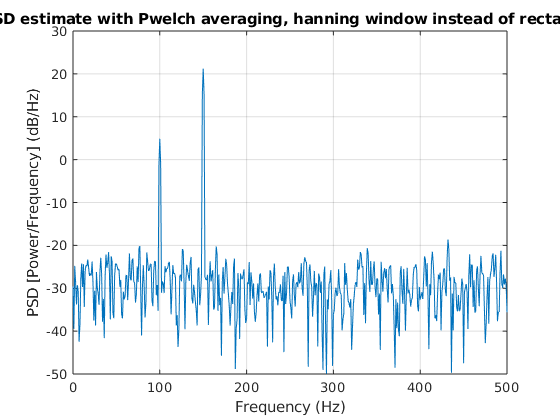

%% Use averging
%%% use 9 overlapping windows, nfft of each window is 1000, 500 noverlap, hanning windowing method
figure
nfft = 1000;
noverlap = nfft/2;
[pxx,ft]=pwelch(x,hanning(nfft),noverlap,nfft,Fs);
plot(ft,10*log10(pxx));
grid on
title('PSD estimate with Pwelch averaging, hanning window instead of rectangle')
xlabel('Frequency (Hz)')
ylabel('PSD [Power/Frequency] (dB/Hz)')

### Defult options

By default, `x` is divided into the longest possible segments to obtain as close to but not exceed 8 segments with 50% overlap. Each segment is windowed with a Hamming window. The modified periodograms are averaged to obtain the PSD estimate. If you cannot divide the length of `x` exactly into an integer number of segments with 50% overlap, `x` is truncated accordingly.** So DO NOT use default options unless you know what you are doing !!!!**

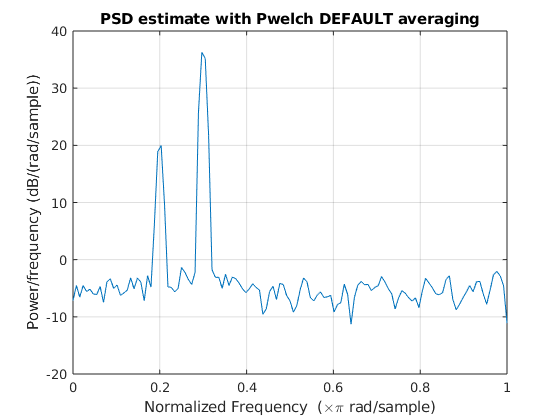

%%% all things are defaults
pwelch(x)
title('PSD estimate with Pwelch DEFAULT averaging')

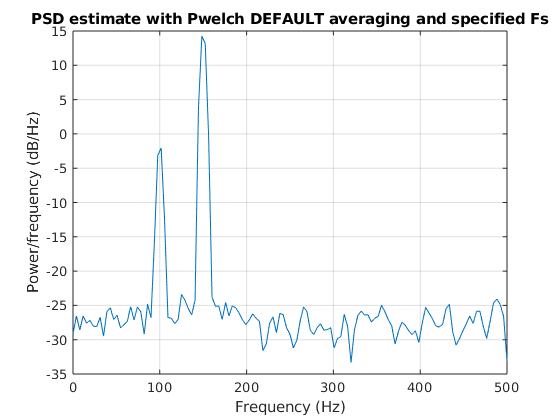


%%% add Fs, changes the x-axis, *Fs/2 and the amplitude
pwelch(x,[],[],[],Fs);
title('PSD estimate with Pwelch DEFAULT averaging and specified Fs')

# Plomb

Lomb-Scargle PSD estimate. Previously we are assuming the signal is sampled at a fixed rate, so that the signal is equally distributed in time. In this senerio, time trace is not necessary to be involved in your analysis. However, there are cases that you are missing samples or sampling rate itself changes due to some reason.

[pxx,f] = plomb(x,t) returns the psd estimate pxx of signal x that is sampled at the instants specified in t. t must increase mononically but need not be uniformly spaced. All elements must be nonnegative. pxx is evaluated at the frequencies returned in f. x and t can contain NaNs or NaTs. These values are treated as missing data and excluded from the spectrum computation. [pxx,f] = plomb(x,fs) treat the case where the signal is sampled uniformly, at a rate fs, but has mssing samples specified with NaNs.

IT is powerful tools, however, in Seismology if we don't know which part of data is missing, or a chunk of data related to the phases we are interested is missing, NaN/zero padding is not suggested. As a result, these data would just be discarded. So this funtion may bot be very useful for Seismology.

# Pmtm

Thompson's Multitaper power spectral density estimate. The tapers are the discrete prolate spheroidal (DPSS), or Slepian, sequences. The time-halfbandwidth, `nw`, product is 4. By default, `pmtm`uses the first 2 × `nw` – 1 DPSS sequences. Time-halfbandwidth product, specified as a positive scalar. Typical choices for nw are 2, 5/2, 3, 7/2, or 4.

In multitaper spectral estimation, the user specifies the resolution bandwidth of the multitaper estimate [-W,W] where W = k/(N dt) for some small k > 1. Equivalently, W is some small multiple of the frequency resolution of the DFT. The time-halfbandwidth product is the product of the resolution halfbandwidth and the number of samples in the input signal, N. The number of Slepian tapers whose Fourier transforms are well-concentrated in [-W,W] (eigenvalues close to unity) is 2NW-1.

If `x` is real-valued, `pxx` is a one-sided PSD estimate. If `x` is complex-valued, `pxx` is a two-sided PSD estimate. The number of points, `nfft`, in the discrete Fourier transform (DFT) is the maximum of 256 or the next power of two greater than the signal length.

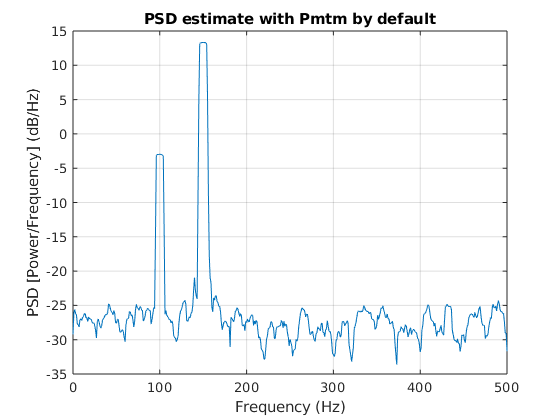

[pxx,ft]=pmtm(x,5,length(x),Fs);
plot(ft,10*log10(pxx));
grid on
title('PSD estimate with Pmtm by default')
xlabel('Frequency (Hz)')
ylabel('PSD [Power/Frequency] (dB/Hz)')

# Pchave, Pchavedemo

Written by Frederick Simons of Princeton. See the function by help it or the code. The Pchavedemo is using pchave to compare with other methods:

- pchavedemo('demo1'): PCHAVE vs. Matlab's PWELCH, both with Hamming window

- pchavedemo('demo2'): PCHAVE's robust estimate; Hamming vs. dpss window

- pchavedemo('demo3'): PCHAVE's robust vs. nonrobust estimate with dpss window

- pchavedemo('demo4'): PCHAVE's robust estimate with linear and logarithmic errors

- pchavedemo('demo5'): PCHAVE's quantile-quantile quality control plots

- pchavedemo('demo6'): PCHAVE's spectral estimates with different confidence intervals

# Some other functions related

- pow2db, convert power to decibel     

db1 = pow2db(1e-3)

db1 = -30

- db,** db1 = db2, **convert power or voltage to decibel

db2 = db(1e-3,'power')

db2 = -30

- findpeaks, to determine the location of the peak of the spectrum. **HELP the function to see more options!**

# Window type 

boxcar (rectwin): a rectangular window;

Hamming;

Hann: also known as a Hanning window, but use the Hann whenever possible instead of Hanning

Taylor;

Triang: triangular

User defined

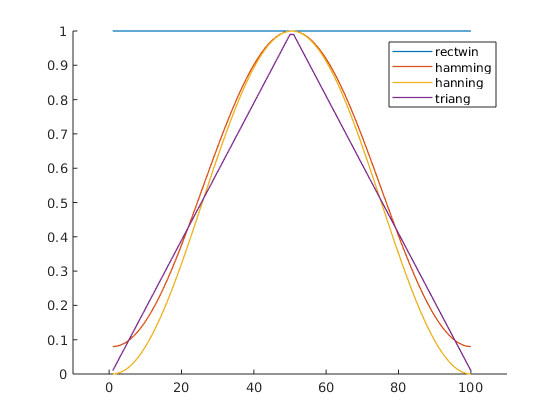

figure
hold on
xlim([-10 110]);
plot(rectwin(100),'LineWidth',1);
plot(hamming(100),'LineWidth',1);
plot(hann(100),'LineWidth',1);
plot(triang(100),'LineWidth',1);
legend({'rectwin','hamming','hanning','triang'});